filename: -0,5V.png_30x30um.png

Number of identified regions:		 30.000000

Number of identified skyrmions:		 23.000000

Number of identified stripe domains:	 7.000000


###############Skyrmion data####################

Mean radius is	9.698437	+- 2.140072 pixels or

		1289.892090	+- 284.629540 nanometers

###############Stripe domain data###############

Mean width is	6.350156	+- 1.619547 pixels or

		844.570709	+- 215.399686 nanometers

Using SDC (Stripe Distance Calculation):

Mean width is	4.346122	+- 1.075141 pixels or

		578.034202	+- 142.993743 nanometers

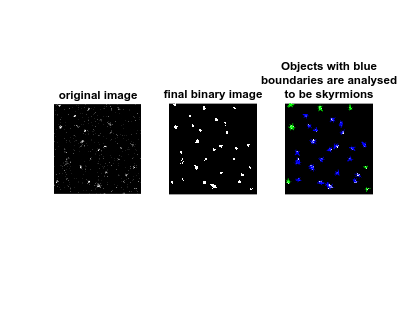

filename: -0,6V.png_30x30um.png

Number of identified regions:		 16.000000

Number of identified skyrmions:		 13.000000

Number of identified stripe domains:	 3.000000


###############Skyrmion data####################

Mean radius is	9.062458	+- 2.132510 pixels or

		1205.306914	+- 283.623821 nanometers

###############Stripe domain data###############

Mean width is	6.647547	+- 2.138655 pixels or

		884.123770	+- 284.441092 nanometers

Using SDC (Stripe Distance Calculation):

Mean width is	4.288771	+- 0.262280 pixels or

		570.406521	+- 34.883291 nanometers

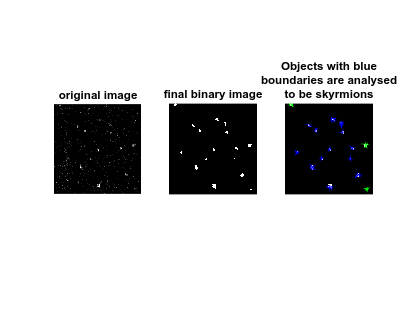

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Skyrmion and stripe domain size calculation script
%   Created by Joonatan Huhtasalo
%   Last Modified: 28.7.2022
%   
%   Based on the script by Bennert Smit
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




clear all
close all
[fname, pname] = uigetfile('aalto/Joonatan/Experimental/*.png', 'MultiSelect','on') ;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Defines the top percent of distance
% data to take into account when calculating
% the width of the stripes
index_param = .1 ;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Width of a pixel in meters
cell_size = .133*10^(-6);%2.5*10^(-9) ;

show_analysis = true;
save_data = true;


if iscell(fname)
    a = numel(fname) ;
else
    a = 1 ;
end

for i = 1:a
    if iscell(fname)
        I = imread(fullfile(pname, fname{i})) ;
        filename = convertCharsToStrings(fname{i});
    else
        %fprintf('/s', fname)
        I = imread(fullfile(pname, fname)) ;
        filename = convertCharsToStrings(fname);
    end
    

    sz = size(I);


    % Turn image to grayscale, invert for further convenience
    % and binarize it
    I1 = im2gray(I);%rgb2gray(I) ;
    I = imgaussfilt(I1, 0.1);


    %I = uint8(255) - I;
    
    leve = graythresh(I);
    BW_gauss = imbinarize(I, 'adaptive');
    
    I2 = bwareaopen(BW_gauss, 20, 4);
    
    %I1 = uint8(255) - I1 ;
    
    %I2 = imbinarize(I1) ;
    
    % Find geometrically distinct features in the image
    % and calculate their properties
    [y,x] = find(I2) ;
    [labeledI2, blobs] = bwlabel(I2) ;
    [B,L,n] = bwboundaries(I2,'noholes') ;
    stats = regionprops(L, 'Circularity', 'MinorAxisLength', 'MajorAxisLength', 'Perimeter', 'FilledArea', 'Centroid') ;
    
    % Initialise few counter variables
    circ_areas = 0 ;
    stripe_domains = 0;
    skyrmion_filled_area = 0;
    stripe_domain_filled_area = 0;
    
    % Get bounding box 
    idx = boundary(x,y) ; 
    R = [x(idx) y(idx)] ; 


    fprintf('filename: %s', filename);

    if show_analysis
        figure;
        subplot(1,3,1), imshow(I1)
        title('original image')
        subplot(1,3,2), imshow(I2)
        title('final binary image')
        subplot(1,3,3), imshow(L)
        title({'Objects with blue', 'boundaries are analysed', 'to be skyrmions'})
        hold on;
    end
    
    % Initialise array variables to store data
    domain_widths = zeros(length(n),2) ;
    skyr_sizes = [] ;
    distance_arrays = [] ;
    avg_widths = [] ;
    
    % Fine tuning parameters
    edge = 20;
    circularity_th = 0.3;
    diameter_min = 4*10^(-9)/cell_size;
    diameter_th = 20000*10^(-9)/cell_size;
    ratio_th = 1.75;
    centroid_min_y = edge;
    centroid_max_y = sz(1)-edge;
    centroid_min_x = edge;
    centroid_max_x = sz(2)-edge;

    
    for k = 1:length(stats)
        % Initialize the comparison variables
        circularity = stats(k).Circularity;
        majoraxis = stats(k).MajorAxisLength;
        minoraxis = stats(k).MinorAxisLength;
        centroid = stats(k).Centroid;

        if (centroid(1) > centroid_min_x) &&...
           (centroid(1) < centroid_max_x) &&...
           (centroid(2) > centroid_min_y) &&...
           (centroid(2) < centroid_max_y) &&...
           (circularity > circularity_th) &&...
           (majoraxis > diameter_min) &&...
           (majoraxis < diameter_th)

            circ_areas = circ_areas + 1 ;
            
            if show_analysis
                plot(B{k}(:,2), B{k}(:,1), 'b','LineWidth',4)
            end
            
            minax = stats(k).MinorAxisLength ;
            majax = stats(k).MajorAxisLength ;
            skyr_sizes(end+1) = majax;
            skyrmion_filled_area = skyrmion_filled_area + stats(k).FilledArea ;
        else
            stripe_domains = stripe_domains + 1 ;
            
            if show_analysis
                plot(B{k}(:,2), B{k}(:,1), 'g','LineWidth',4)
            end

            thisBlob = ismember(labeledI2, k) ;
            edtImage = bwdist(imcomplement(thisBlob)) ;
            
            dists = edtImage(:) ;
            dists(dists == 0) = [] ;
            dists = sort(dists, 'descend') ;
            idx = int8(round(index_param*length(dists)));
    
            % Width from the SDC
            avg_widths(end+1) = 2*mean(dists(1:idx)) ;
            
            % Width as the minor axis of bounding ellipse
            domain_widths(k,1) = stats(k).MinorAxisLength ;
    
    
            stripe_domain_filled_area = stripe_domain_filled_area + stats(k).FilledArea ;
        end
    end
    
    
    
    % Skyrmion radius means and std
    skyr_mean_r = mean(skyr_sizes);
    skyr_std = std(skyr_sizes) ;
    
    smean_nm = skyr_mean_r*cell_size*10^9 ;
    sstd_mn = skyr_std*cell_size*10^9 ;
    
    
    % Stripe domain means and stds
    mean_width = mean(nonzeros(domain_widths(:,1))) ;
    std_width = std(nonzeros(domain_widths(:,1))) ;
    
    cmean_width = mean(avg_widths) ;
    cstd_width = std(avg_widths) ;
    
    mn_width_nm = mean_width*cell_size*10^9 ;
    std_width_nm = std_width*cell_size*10^9 ;
    
    cmn_width_nm = cmean_width*cell_size*10^9 ;
    cstd_width_nm = cstd_width*cell_size*10^9 ;
    
    
%     fprintf('Number of identified regions:\t\t %f', n)
%     fprintf('Number of identified skyrmions:\t\t %f', circ_areas)
%     fprintf('Number of identified stripe domains:\t %f\n', stripe_domains)
%     
%     fprintf('###############Skyrmion data####################')
%     fprintf('Mean radius is\t%f\t+- %f pixels or', skyr_mean_r, skyr_std)
%     fprintf('\t\t%f\t+- %f nanometers', smean_nm, sstd_mn)
%     
%     
%     fprintf('###############Stripe domain data###############') 
%     fprintf('Mean width is\t%f\t+- %f pixels or', mean_width, std_width)
%     fprintf('\t\t%f\t+- %f nanometers', mn_width_nm, std_width_nm)
%     
%     fprintf('Using SDC (Stripe Distance Calculation):')
%     fprintf('Mean width is\t%f\t+- %f pixels or', cmean_width, cstd_width)
%     fprintf('\t\t%f\t+- %f nanometers', cmn_width_nm, cstd_width_nm)
    
    skyrmion_number = circ_areas ;
    avg_skyrmion_size = smean_nm ;
    std_skyrmion_size = sstd_mn ;
    
    stripe_domain_number = stripe_domains ;
    avg_stripe_domain_size = cmn_width_nm ;
    std_stripe_domain_size = cstd_width_nm ;
    
    % Convert area variables to square nanometers
    skyrmion_filled_area = skyrmion_filled_area*cell_size^2*(10^9)^2 ;
    stripe_domain_filled_area = stripe_domain_filled_area*cell_size^2*(10^9)^2 ;
    
    table_out(i,:) = table(filename, skyrmion_number,avg_skyrmion_size,std_skyrmion_size, skyrmion_filled_area,stripe_domain_number,avg_stripe_domain_size,std_stripe_domain_size, stripe_domain_filled_area);
    
    if show_analysis
        hold off;
    end

end


if save_data
    writetable(table_out, fullfile(pname, 'data.csv'));
end
